simout = Get_Sim_Output(out)

simout = struct with fields:
     time: [908×1 double]
        x: [908×6 double]
    utraj: [400×2×751 double]
    xtraj: [400×6×751 double]


num_timestep = size(simout.utraj, 1);
num_optim = size(simout.utraj, 3);
op_time = 0.04;
dtime = linspace(0.2, 0.2, num_optim);
offset = op_time * (0:num_optim-1);
scaled = (dtime' * (0:num_timestep-1))';
solution_time = offset + scaled;
min_sol_time = min(solution_time,[],"all");
max_sol_time = max(solution_time,[],"all");
min_dtime = min(dtime,[],"all");
min_optime = min(op_time,[],"all");
k = linspace(min_sol_time, max_sol_time, num_optim);

q = linspace(0, max(simout.time), num_optim)

q =          0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    1.0400    1.0800    1.1200    1.1600    1.2000    1.2400    1.2800    1.3200    1.3600    1.4000    1.4400    1.4800    1.5200    1.5600    1.6000    1.6400    1.6800    1.7200    1.7600    1.8000    1.8400    1.8800    1.9200    1.9600


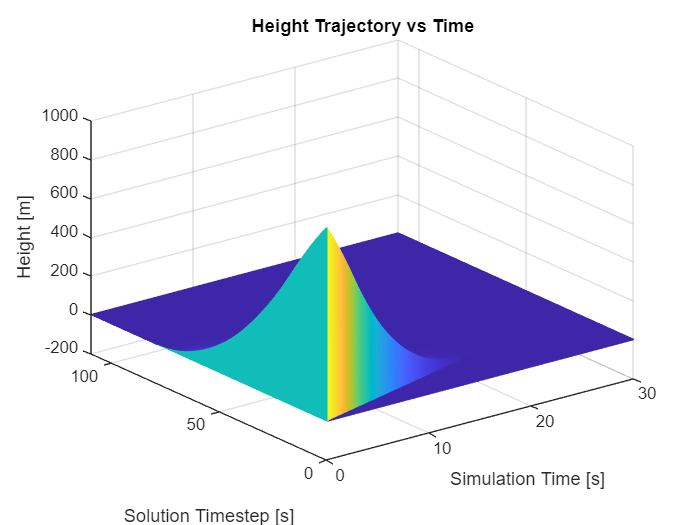

c = min_sol_time:op_time:max_sol_time;

[X, Y] = meshgrid(q,c);

new_val = zeros(numel(c), numel(q));
for i = 1:length(q) 
    new_val(:, i) = interp1(solution_time(:,i), simout.xtraj(:,2,i), c, 'linear', 0); 
end

waterfall(X, Y, new_val);
xlabel("Simulation Time [s]")
ylabel("Solution Timestep [s]")
zlabel("Height [m]")
title("Height Trajectory vs Time")

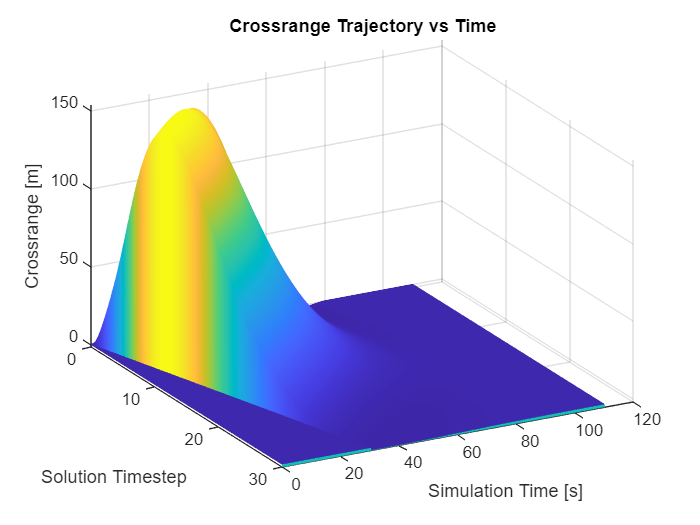

%Z = squeeze(simout.xtraj(:,2,:));
%[X, Y] = meshgrid(1:size(simout.utraj, 1),(1:size(simout.utraj, 3))/size(simout.utraj, 3) * max(simout.time));
%waterfall(solution_time, solution_time, Z);
%xlabel("Simulation Time [s]")
%ylabel("Solution Timestep")
%zlabel("Height [m]")
%title("Height Trajectory vs Time")
%view([61.4 29.4])

%= Crossrange Trajectory: 

%Z = squeeze(simout.xtraj(:,1,:));
%[X, Y] = meshgrid(1:size(simout.utraj, 1),(1:size(simout.utraj, 3))/size(simout.utraj, 3) * max(simout.time));
%waterfall(X,Y,new_val');

new_val_2 = zeros(numel(c), numel(q));
for i = 1:length(q) 
    new_val_2(:, i) = interp1(solution_time(:,i), simout.xtraj(:,1,i), c, 'linear', 0); 
end

waterfall(X, Y, new_val_2); % do i include it as new_val_2'
ylabel("Simulation Time [s]")
xlabel("Solution Timestep")
zlabel("Crossrange [m]")
title("Crossrange Trajectory vs Time")


view([61.4 29.4])

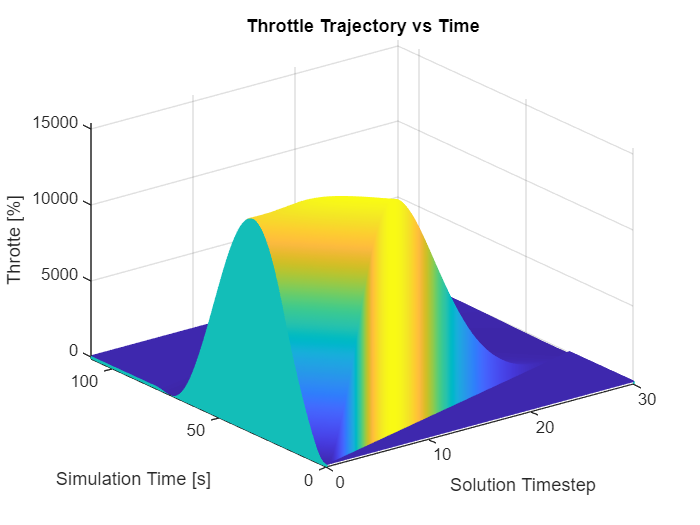

%Z = squeeze(simout.utraj(:,1,:));
waterfall(X, Y, new_val_2 * 100);
ylabel("Simulation Time [s]")
xlabel("Solution Timestep")
zlabel("Throtte [%]")
title("Throttle Trajectory vs Time")

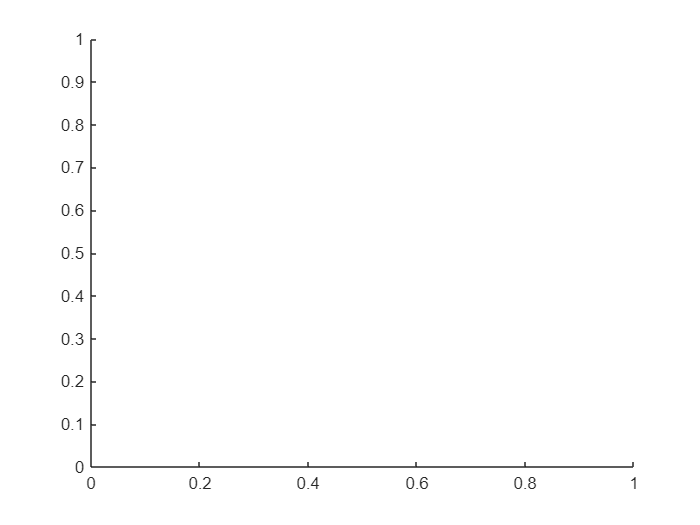

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

Error in waterfall (line 60)
z = [z0*ones(size(x,1),1) z(:,1) z z(:,size(z,2)) z0*ones(size(x,1),2) ];

Z = squeeze(simout.xtraj(:,3,:));
waterfall(Y, X, Z');

ylabel("Simulation Time [s]")
xlabel("Solution Timestep")
zlabel("Horizontal Velocity [m/s]")
title("Horizontal Velocity Trajectory vs Time")

Z = squeeze(simout.xtraj(:,4,:));
waterfall(Y, X, Z');
ylabel("Simulation Time [s]")
xlabel("Solution Timestep")
zlabel("Vertical Velocity [m/s]")
title("Vertical Velocity Trajectory vs Time")

Z = squeeze(rad2deg(simout.xtraj(:,5,:)));
waterfall(Y, X, Z');
xlabel("Simulation Time [s]")
ylabel("Solution Timestep")
zlabel("Orientation [deg]")
title("Orientation Trajectory vs Time")

Z = squeeze(rad2deg(simout.utraj(:,2,:)));
waterfall(Y, X, Z');
xlabel("Simulation Time [s]")
ylabel("Solution Timestep")
zlabel("Gimbal [deg]")
title("Gimbal Trajectory vs Time")

%Z = squeeze(simout.x(:,1,:));
%[X, Y] = meshgrid(1:size(simout.utraj, 1),(1:size(simout.utraj, 3))/size(simout.utraj, 3) * max(simout.time));
%waterfall(X, Y, Z');
%ylabel("Simulation Time [s]")
%xlabel("Solution Timestep")
%zlabel("Crossrange [m]")
%title("Crossrange Trajectory vs Time")

simout.u